# Worksheet 4

In this worksheet, we switch to differential equations for functions with more than one independent variable, for example functions depending on several space dimensions.

Such differential equations are called partial differential equations. We start with a first simple example, the two-dimensional stationary heat equation

$T_{xx} + T_{yy} = -2\pi^2 \sin(\pi x) \sin(\pi y)$    (1)

on the unit square $\Omega =]0, 1[^2$ with the temperature $T (x, y)$, the two-dimensional coordinates $x$ and $y$, and homogeneous Dirichlet boundary conditions

$T (x, y) = 0 \quad \forall (x, y) \in \partial \Omega$.    (2)

The boundary value problem (1),(2) has the analytical solution

$T (x, y) = \sin(\pi x) \sin(\pi y)$.    (3)

**a)** The discretization of (1) and (2) leads to a large system of linear equations for the values $T_{i,j}$ , $i \in \{1, \dots , N_x \}$, $j \in \{1, \dots , N_y\}$ denoting the approximate values of the temperature $T$ at the discrete grid points $\left( i \cdot \frac{1}{N_x+1} , j \cdot \frac{1}{N_y+1}\right)$ .

Use the finite difference approximation of the second derivatives

$T_{xx} |_{i,j} \approx \frac {T_{i-1,j} - 2T_{i,j} + T_{i+1,j}}{h^2_x}$ ,


$$T_{yy} |_{i,j} \approx \frac {T_{i,j-1} - 2T_{i,j} + T_{i,j+1}}{h^2_y}$$


with $h_x = \frac{1} {N_x+1}$ and $h_y = \frac{1} {N_y+1}$ .

Sketch a few lines of the resulting system in the following scheme

[...]

**b)** Implement a function creating the matrix from **a)** as a function of $N_x$ and $N_y$ .

*(N.B. implemented in a separate file)*

#### `function A = full_matrix(N_x, N_y)`

#### `        h2_x = (1/(N_x+1))^2;`

#### `        h2_y = (1/(N_y+1))^2;`

#### `        d = (-2/h2_x-2/h2_y)*ones(N_x*N_y,1);`

#### `        c = 1/h2_y*ones(N_x*N_y-1,1);`

#### `        c (N_x:N_x:end) = 0;    % takes into account the jump on the next column by setting the corresponding element to zero`

#### `        e = 1/h2_x*ones(N_x*N_y-N_x,1);`

#### `        A = diag(d)...       % main diagonal matrix`

#### `            +diag(c,1)...    % first upper diagonal`

#### `            +diag(c,-1)...   % first lower diagonal`

#### `            +diag(e, N_x)... % second upper diagonal at +N_x`

#### `            +diag(e, -N_x);  % second lower diagonal at -N_x`

#### `end`

**c)** Since the matrix created in **b)** is mostly composed of zeros, and only a few entries are nonzero, it is advantageous to directly create a sparse matrix. Thus, implement a different function creating the matrix from **a)** as a function of $N_x$ and $N_y$ in sparse format.

**Remark:** Do NOT(!!!) call `sparse(A)`, as this assumes that you have the full/dense matrix beforehand—and this is exactly what we are trying to avoid.

Instead, use your knowledge on the matrix structure to build it up.

*(N.B. implemented in a separate file)*

#### `function A = sparse_matrix(N_x, N_y)`

####         `h2_x = (1/(N_x+1))^2;`

####         `h2_y = (1/(N_y+1))^2;`

####         `d = (-2/h2_x-2/h2_y)*ones(N_x*N_y,1);`

####         `c = 1/h2_y*ones(N_x*N_y-1,1);                                                         % upped diagonal`

####         `c (N_x:N_x:end) = 0; % takes into account the jump on the next column`

####         `e = 1/h2_x*ones(N_x*N_y-N_x,1);                                                       %lower diagonal`

####         `x = [1:(N_x*N_y),2:(N_x*N_y),1:(N_x*N_y-1),(N_x+1):(N_x*N_y),1:(N_x*N_y-N_x)];        % x indices of non-zero elements`

####         `y = [1:(N_x*N_y),1:(N_x*N_y-1),2:(N_x*N_y),1:(N_x*N_y-N_x),(N_x+1):(N_x*N_y)];        % y indices of non-zero elements`

####         `A = sparse(x,y,cat(1,d, c, c, e, e));        % creates sparse matrix with non-zero elements specified by x, y and their values`

#### `end`

**d)** Implement a Gauss-Seidel solver for the system in **a)** as a function of the right hand side $b$, $N_x$ , and $N_y$ . The output of the solver is a matrix with dimensions $N_x$ and $N_y$ containing the computed approximate values of $T$ at the grid points $(i \cdot h_x , j \cdot h_y )$ in entry $(i, j)$. As a termination criterion for the iteration use an accuracy limit of $10^{-4}$ for the residual norm.

**Remark 1:** Do NOT(!!!) use the explicit system matrices from **b)** or **c)** in your Gauss-Seidel solver. Use your knowledge about the particular, constant form of the lines of the linear system to completely avoid any storage of matrix entries!

**Remark 2:** Think about the how to handle the boundary points for an efficient traversal of the mesh! Also, remember to only return the inner domain values from your Gauss-Seidel implementation!

**Remark 3:** The residual norm for a general system $Ax = b$ is defined as

$R = \sqrt{\frac{1}{N}\sum_k\left(b_k-\sum_m a_{k,m}x_m\right)^2}$,

where $N$ denotes the number of unknowns. In the Gauss-Seidel solver, $N = N_x \cdot N_y$ , $a_{i,j}$ are not stored (but known), and the entries of $x$ are the temperature values $T_{i,j}$ at the grid points $(i \cdot h_x , j \cdot h_y )$.

*(N.B. implemented in separate files)*

#### `function r = residual_norm(N_x, N_y, b, x)`

####         `h2_x = (1/(N_x+1))^2;     % grid spacing in x direction`

####         `h2_y = (1/(N_y+1))^2;     % grid spacing in y direction`

####         `d = -2/h2_x-2/h2_y; % main diagonal element`

####         `c = 1/h2_y;                 % upper and lower diagonal element`

####         `e = 1/h2_x;                 % second upper and lower diagonal element (+/-N_x diagonal)`

####         `N = N_x*N_y;`

####         `g = zeros(N,1);`

####         `for i=1:N`

####         `    s=0;`

####         `    if(i>N_x)`

####         `        s=s+e*x(i-N_x);     % second upper diagonal element (+N_x diagonal)`

####         `    end`

####         `    if(i>1 && mod(i,N_x)~=1)`

####         `        s=s+c*x(i-1);     % lower diagonal element`

####         `    end`

####         `    if(i<N&& mod(i,N_x)~=0)`

####         `        s=s+c*x(i+1);     % upper diagonal element`

####         `    end`

####         `    if(i<N-N_x)`

####         `        s=s+e*x(i+N_x);     % second lower diagonal element (-N_x diagonal)`

####         `    end`

####         `    s = s+d*x(i);          % diagonal element`

####         `    g(i) = (b(i)-s)^2;     % calculate the square of residual`

####         `end`

####         `r = sqrt(1/N*sum(g,'all')); % calculate the residual norm`

#### `end`

`----------------------------------------`

#### `function x = gauss_seidel(b, N_x, N_y)`

####         `d = -2/((1/(N_x+1))^2)-2/((1/(N_y+1))^2);    % main diagonal`

####         `c = 1/((1/(N_y+1))^2);                       % upper and lower diagonal`

####         `e = 1/((1/(N_x+1))^2);                       % second upper and lower diagonal`

####         `rnorm = inf;                                 % residual norm is set to infinity as an initial value`

####         `N = N_x*N_y;                                 % total number of grid points`

####         `x = zeros(N,1);                              % initialize solution vector x with all zeros`

####         `j=0;`

####         `while rnorm > 1e-4 ` `% iterate until the residual norm is below 1e-4`

####         `    j=j+1;`

####         `    for i=1:N`

####         `        sum=0;`

####         `        if(i>N_x)`

####         `            sum=sum+e*x(i-N_x);           % second upper diagonal`

####         `        end`

####         `        if(i>1 && mod(i,N_x)~=1)`

####         `            sum=sum+c*x(i-1);             % lower diagonal`

####         `        end`

####         `        if(i<N&& mod(i,N_x)~=0)`

####         `            sum=sum+c*x(i+1);             % upper diagonal`

####         `        end`

####         `        if(i<N-N_x)`

####         `            sum=sum+e*x(i+N_x);           % second lower diagonal`

####         `        end`

####         `        x(i) = 1/d*(b(i)-sum);            % update solution vector x`

####         `    end`

####         `    rnorm=residual_norm(N_x, N_y, b, x);  % calculate the residual norm`

####         `end`

####         `x = reshape(x, N_x, N_y);                 % reshape x into a matrix with dimensions N_x, N_y`

#### `end`

**e)** Solve the system $Ax = b$ from **a)**

**1)** storing the system matrix as a “normal” (i.e., full) $N \times N$ matrix and using the MATLAB direct solver,

**2)** storing the system matrix as a sparse matrix and using the MATLAB direct solver,

**3)** without storing the system matrix (use Gauss-Seidel with zero as initial guess for $T$ !).

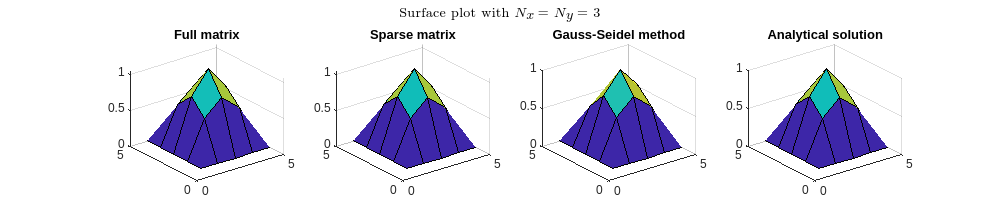

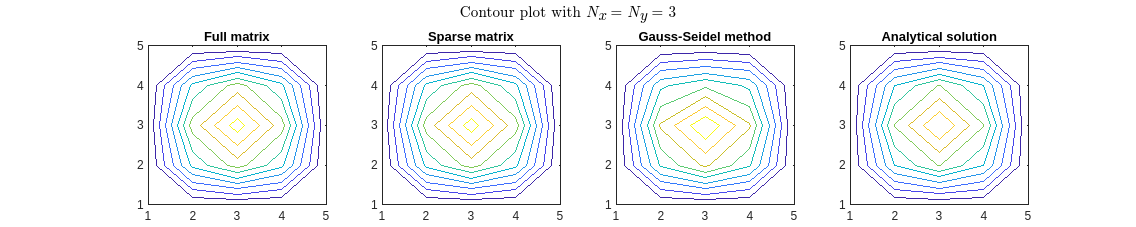

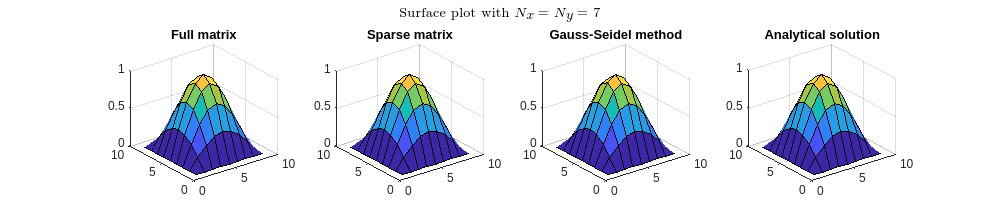

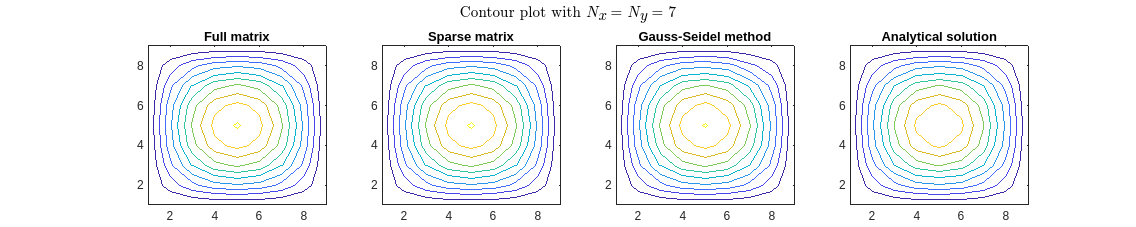

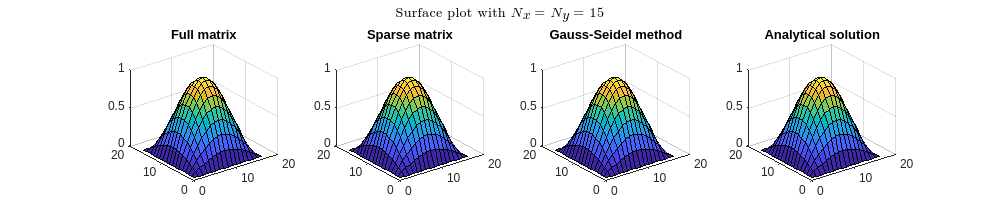

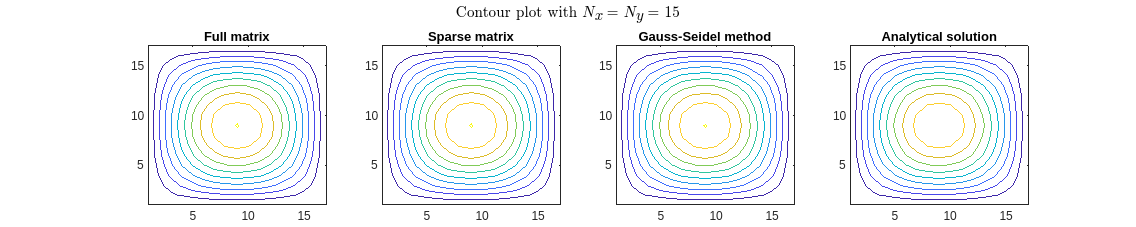

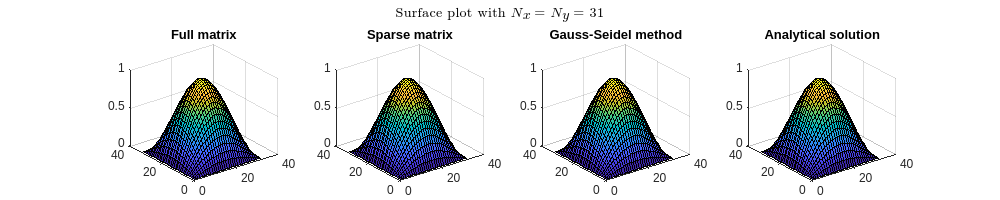

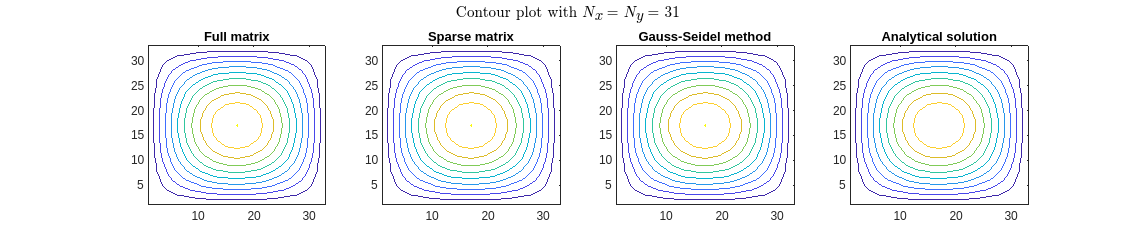

clear all
close all
clc
N = [3 7 15 31 63];
f = @(x,y) -2*pi^2*sin(pi*x)*sin(pi*y);
solution_f = @(x,y) sin(pi*x)*sin(pi*y);

full_time = zeros(1,length(N));
sparse_time = zeros(1,length(N));
GS_time = zeros(1,length(N));

for i = 1:length(N)

    N_x = N(i);
    N_y = N(i);

    b = populate_vector(N_x,N_y,f);

    %% 1
    tic
    A_full = full_matrix(N_x, N_y);
    x_full = reshape(A_full\b, N_x, N_y);
    full_time(i) = toc;
    x_full_b = add_bound(x_full, N_x, N_y);

    %% 2
    tic
    A_sparse = sparse_matrix(N_x, N_y);
    x_sparse = reshape(A_sparse\b, N_x, N_y);
    sparse_time(i) = toc;
    x_sparse_b = add_bound(x_sparse, N_x, N_y);

    %% 3
    tic
    x_GS = gauss_seidel(b,N_x,N_y);
    GS_time(i) = toc;
    x_GS_b = add_bound(x_GS, N_x, N_y);

    %% analytical solution
    x_real = reshape(populate_vector(N_x,N_y, solution_f), N_x, N_y);
    x_real_b = add_bound(x_real, N_x, N_y);

    %% surface plot
    h = figure;
    subplot(1,4,1)
    surf(x_full_b);
    title('Full matrix')
    subplot(1,4,2)
    surf(x_sparse_b);
    title('Sparse matrix')
    subplot(1,4,3)
    surf(x_GS_b);
    title('Gauss-Seidel method')
    subplot(1,4,4);
    surf(x_real_b);
    title('Analytical solution')

    sgtitle("Surface plot with $N_x$ = $N_y$ = " + N(i), 'interpreter', 'latex')
    set(h,'Position', [0 0 1000 200])

    %% contour plot
    h = figure;
    subplot(1,4,1)
    contour(x_full_b);
    title('Full matrix')
    subplot(1,4,2)
    contour(x_sparse_b);
    title('Sparse matrix')
    subplot(1,4,3)
    contour(x_GS_b);
    title('Gauss-Seidel method')
    subplot(1,4,4);
    contour(x_real_b);
    title('Analytical solution')

    sgtitle("Contour plot with $N_x$ = $N_y$ = " + N(i), 'interpreter', 'latex')
    set(h,'Position', [0 0 1250 250])

end

**f)** Visualize the solutions as a

**1)** a coloured surface where the temperature represents the height of the surface,

**2)** a contour plot.

for $N_x = N_y = 3, 7, 15, 31, 63$. Set the range of the temperature values so that the surface doesn’t look flat. Think about a reasonable range.

**Remark:** Also include the boundary values i.e. your plot should contain $(N_x +2) \cdot (N_y + 2)$ data points.

**g)** Compare the runtimes and the storage requirements (measured by the number of doubles needed to store the matrices and vectors) for 1) – 3) in a) and for $N_x = N_y = 7, 15, 31, 63$,127:

direct_solution_full_table = table([N(2) full_time(2) N(2)^4]', [N(3) full_time(3) N(3)^4]', [N(4) full_time(4) N(4)^4]',...
    [N(5) full_time(5) N(5)^4]','rownames', {'N_x, N_y', 'runtime', 'storage'}, 'VariableNames', ...
    {'7', '15', '31','63'} );
T = table(direct_solution_full_table,'VariableNames',{'direct solution with full matrix'}); % Nested table
disp(T)

                  direct solution with full matrix              
                   7           15           31            63    
    ____________________________________________________________

    N_x, N_y           7          15            31            63
    runtime     0.008059    0.014111       0.07608        1.9158
    storage         2401       50625    9.2352e+05    1.5753e+07



direct_solution_sparse_table = table([N(2) sparse_time(2) N(2)^2+2*(N(2)^2-1)+2*(N(2)^2-N(2))]',...
                                    [N(3) sparse_time(3) N(3)^2+2*(N(3)^2-1)+2*(N(3)^2-N(3))]',...
                                    [N(4) sparse_time(4) N(4)^2+2*(N(4)^2-1)+2*(N(4)^2-N(4))]',...
                                    [N(5) sparse_time(5) N(5)^2+2*(N(5)^2-1)+2*(N(5)^2-N(5))]',...
                                    'rownames', {'N_x, N_y', 'runtime', 'storage'}, 'VariableNames', ...
                                    {'7', '15', '31','63'} );
T = table(direct_solution_sparse_table,'VariableNames',{'direct solution with sparse matrix'}); % Nested table
disp(T)

              direct solution with sparse matrix           
                   7           15         31          63   
    _______________________________________________________

    N_x, N_y           7          15         31          63
    runtime     0.003358    0.001149    0.00284    0.016162
    storage          229        1093       4741       19717



iterative_solution_gs_table = table([N(2) GS_time(2) 3]', [N(3) GS_time(3) 3]', [N(4) GS_time(4) 3]',...
    [N(5) GS_time(5) 3]','rownames', {'N_x, N_y', 'runtime', 'storage'}, 'VariableNames', ...
    {'7', '15', '31','63'} );
T = table(iterative_solution_gs_table,'VariableNames',{'iterative solution with Gauss-Seidel'}); % Nested table
disp(T)

            iterative solution with Gauss-Seidel         
                   7           15         31         63  
    _____________________________________________________

    N_x, N_y           7          15         31        63
    runtime     0.008845    0.007294    0.18557    3.4688
    storage            3           3          3         3



**Remark 1:** Consider in the runtime both the matrix construction (if applicable) and the system solution, as this enables a more fair comparison across all three methods.

**Remark 2:** If your Gauss-Seidel runtime is unexpectedly high then this is a sign of a poorly implemented solver!

**h)** Compute the solutions for $N_x = N_y = 7, 15, 31, 63, 127$ with the Gauss-Seidel solver and fill in the resulting errors


$$e=\sqrt{\frac{1}{N_x \cdot N_y}\sum_{j=1}^{N_y}\sum_{i=1}^{N_x}(T_{i,j}-T(x_i,y_j))^2}$$


in the following tabular:

N = [7 15 31 63 127];
f = @(x,y) -2*pi^2*sin(pi*x)*sin(pi*y);
solution_f = @(x,y) sin(pi*x)*sin(pi*y);
err = zeros(1,length(N));
for i = 1:length(N)
    N_x = N(i);
    N_y = N(i);
    b = populate_vector(N_x,N_y,f);
    x_GS = gauss_seidel(b,N_x,N_y);
    x_real = reshape(populate_vector(N_x,N_y, solution_f), N_x, N_y);
    err(i) = sqrt(1/(N_x*N_y)*sum((x_GS-x_real).^2, 'all'));
end
err_red = err(1:end-1)./err(2:end);
error_table = table([N(1) err(1) nan]', [N(2) err(2) err_red(1)]', [N(3) err(3) err_red(2)]',...
    [N(4) err(4) err_red(3)]', [N(5) err(5) err_red(4)]','rownames', {'N_x = N_y', 'error', 'error red.'}, 'VariableNames', ...
    {'7', '15', '31','63', '127'} );
disp(error_table)

                      7           15            31            63           127    
                  _________    _________    __________    __________    __________

    N_x = N_y             7           15            31            63           127
    error         0.0083573    0.0017831    0.00041451    9.7307e-05    2.0274e-05
    error red.          NaN        4.687        4.3017        4.2598        4.7995

